# Scheduling algorithm

## Introduction

The scheduling algorithm updates the parameters smoothly from their initial values $p_{\textrm{start}}$ to their final values $p_{\textrm{end}}$. The following update rule is used:


$$p=\lambda \left(i\right)\cdot \left(p_{\textrm{start}} -p_{\textrm{end}} \right)+p_{\textrm{end}}$$


with $\lambda \left(i\right)$ the value of the schedule parameter at iteration $i$. It evolves from $1$ downto $0$.

If the problem to be solved is smooth enough and feasible for every parameter values, taking small parameters steps allows solving the problem. However, if the steps are too small, the algorithm will be slow. If the steps are too large, the obtained problem may not be solvable. A compromise has to be found.

Two approaches are proposed to update $\lambda$: a *linear* schedule and a *logarithmic* schedule. These algorithms are also responsible to reduce the step size when the current iteration failed.

## Tuning guideline

First you need to select a scheduler. For numerically "simple" problems, the linear scheduled should be sufficient. It has the proprerty that the final values of the continuation parameters will be reached in a finite number of iterations.

The logarithmic schedule is suitable for some numerically difficult problems, such as those occuring state constraint within an optimal control problem. This algorihthm does not allow the continuation parameters to actually reaches their final values, but instead the algorithm converges asymptotically.

### Step size `delta`

The initial value of $\delta$ can be passed as a name-value parameter using "delta". 

For the *linear* schedule, the `delta` value should be close to 0 (but positive). Small step size, e.g. `delta=0.01`, leads to BVP possibly easier to solve but long computation time. Larger step size, e.g. `delta=0.25`, will lead to possibly more diffcult BVP to solve but less iterations.

For the *logarithmic* schedule, the `delta` value should be close to 1 (but stricly inferior). Values close to 1, e.g. `delta=0.99`, leads to BVP possibly easier to solve but longer computation time. Smaller values, e.g. `delta=0.5`, will lead to possibly more diffcult BVP to solve but less iterations.

### Step size update parameter `beta`

At every iteration, the step size is adjusted depending wether or not the BVP has been solved. When $\beta$ is close to one, e.g. `beta=1.01`,the step size variation between to iterations is small. When $\beta$ is larger, e.g. `beta=1.5`, the step size is increased or decreased (depending on wether or not the last BVP was solved) with larger variations.

### Stopping parameter `deltaStop`

In order to prevent an infinite number of continuation procedure iterations, the continuation procedure is stopped when the schedule parameter $\lambda$ asymptotically reaches the $\lambda_{\textrm{Last}\_\textrm{success}}$ the values that lead to the last solved BVP.

The `deltaStop` parameter is a value between 0 and 1 (excluded) that allows to control when the algorithm need to be stopped. A small value, e.g. `deltaStop=1e-4`, will possibly allows to go thru very difficult problem, even if the computation time become intractable. A large value, e.g. `deltaStop=0.01`, will stop the algorithm quite early.

### Programming syntax

Schedulers are derived from the abstract class `abstractScheduler`. The provided schedulers are: `linearScheduler` and `logScheduler`.

The minimmal syntax is : 

scheduler=linearScheduler(paramStart,paramEnd);
scheduler=logScheduler(paramStart,paramEnd);

## Linear scheduler

### Sucessful iterations

After every successful iteration, the current step size is updated as :

 $\delta \left(i+1\right)=\delta \left(i\right)\cdot \beta$ with $\beta >1$.

The schedule parameter $\lambda$ is updated as: $\lambda \left(i+1\right)=\lambda \left(i\right)-\delta \left(i+1\right)$

with $\delta \left(i+1\right)\;$the step size at iteration $i+1$.

As a result, the step size is (slightly) increased after every sucessfull iteration while $\lambda$ decreases.

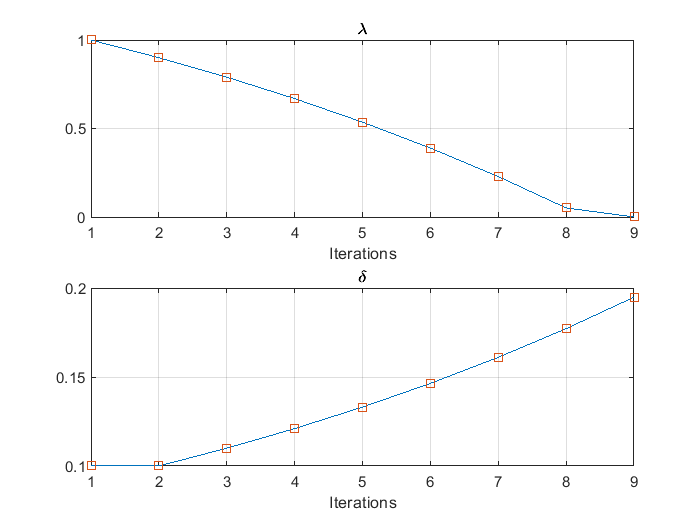

### Failed iterations

When a boundary value problem cannot be solved, a smaller step is needed. So the step size is updated as  : 

$\delta \left(i+1\right)=\frac{\delta \left(i\right)}{\beta }$ with $\beta >1$

The schedule parameter is updated starting from the last value that lead to a sucessfull iteration:


$$\lambda \left(i+1\right)=\lambda_{\mathrm{Last}\_\mathrm{success}} -\delta \left(i+1\right)$$


The following figure illustrate the algorithm behavior. The BVP problem is sucessfully solved up to iteration n°3 but fails at iteration n°4. 

As a result, the continuation paramter is updated starting from the last value of $\lambda \left(3\right)$ with smaller step $\delta \left(i\right)$. 

In order to avoid performing an infinite number of failed attempt at solving the BVP, the algorithm is solved when $\delta \left(i\right)\;$ reaches a minimum threshold for instance `deltaMin=1e-2`.

In the following figure, the first 3 iterations are a success, so the step size  $\delta \left(i\right)\;$  is increased. The bvp at iteration cannot be solved. As a result, $\delta$ is decreased until the problem becomes feasible.

At iteration n°10, the problem is not solvable anymore. As a result, the step size  $\delta \left(i\right)\;$ is decreases and becomes smaller than  `deltaMin `at iteration 35. Then the algorithm stops.

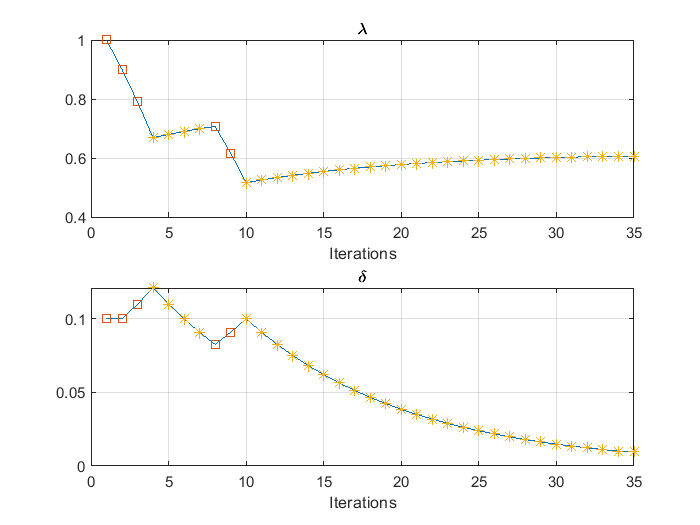

## Logarithmic scheduler

### Sucessful iterations

After every successful iteration, $\lambda_{\textrm{Last}\_\textrm{success}} =\lambda \left(i\right)$ is stored as the last known feasible schedule parameter.

The  $\delta$ coefficient  is updated as :

 $\delta \left(i+1\right)=\frac{\delta \left(i\right)}{\beta }$ with $\beta >1$.

The schedule parameter $\lambda$ is updated as: $\lambda \left(i+1\right)=\lambda_{\mathrm{Last}\_\mathrm{success}} \cdot \delta \left(i+1\right)$ .

As a result, the step size coefficient $\delta$ is (slightly) decreased after every sucessfull iteration thus allowing the schedule step size $\lambda$ to converge faster toward 0. Note that the schedule parameter $\lambda$ cannot exactly reach 0 but only converges toward 0.

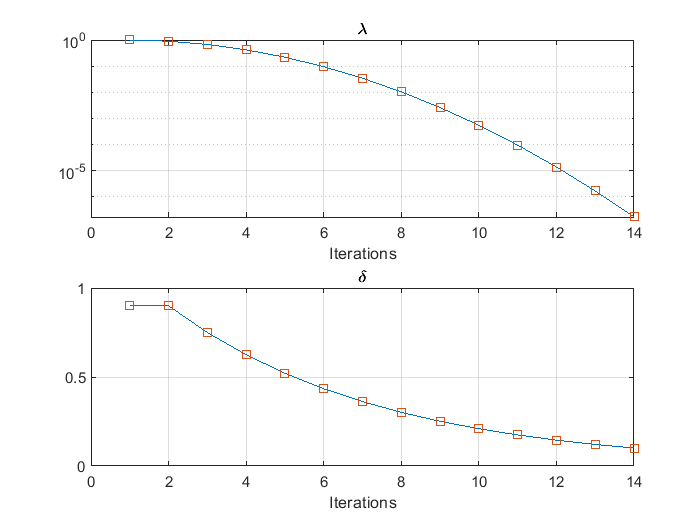

### Failed iterations

When a boundary value problem cannot be solved, a smaller step is needed. Let us denote by $\lambda_{\textrm{Last}\_\textrm{success}}$ the last value of the schedule parameter that allowed to solve the bvp.

The schedule coefficient $\delta$ is updated using a cumbersome but working formula  : 

$\delta \left(i+1\right)=1-\frac{\left(\lambda_{\mathrm{Last}\_\mathrm{success}} -\lambda \left(i\right)\right)}{\lambda_{\mathrm{Last}\_\mathrm{success}} }\cdot \left(1-\frac{1}{\beta }\right)$ with $\beta >1$

The schedule parameter $\lambda \;$is updated starting from the last value that lead to a sucessfull iteration:


$$\lambda \left(i+1\right)=\lambda_{\mathrm{Last}\_\mathrm{success}} \cdot \delta \left(i+1\right)$$


The following figure illustrate the algorithm behavior. Mind that the y-axis of the first subplot is using a logarithmic scale.

From iterations 1 to 3, the BVP problem is sucessfully solved. As a result, the schedule coefficient $\delta \left(i\right)$ is progressively decreased.

At iteration n°4, the algorithm fail, so the schedule coefficient $\delta \left(i\right)$ is progressively increased back to the value 1. The result is that the schedule parameter $\lambda$ will assymptotically reach the last sucessful value $\lambda_{\textrm{Last}\_\textrm{success}}$.

At iteration 8 & 9, the BVP is solved, so the schedule parameter $\lambda$ is decreased as well as the schedule coefficient $\delta$.

After iteration 10,  the BVP cannot be solved anymore. The step size $\delta \left(i\right)$ is decreased ans $\lambda$ converge assymptoticaly toward $\lambda_{\textrm{Last}\_\textrm{success}}$ while the schedule coefficient $\delta$ converges toward 1.

The continuation procedure is stopped as soon as the schedule coefficient $\delta$ becomes too close from 1 : $1-\delta$<`deltaMin `with` deltaMin ` being 1e-4 for this example.